% Clear (!!!Save your workspace first!!!)
clc;
clear;
close all;
load('dataset.mat')

% data set from tracker
t = J1dataset.t;
% Position
x0 = J0dataset.x;   % Joint 0 (Foot)
y0 = J0dataset.y;
x1 = J1dataset.x;   % Joint 1 (Ankel)
y1 = J1dataset.y;
x2 = J2dataset.x;   % Joint 2 (Knee)
y2 = J2dataset.y;
x3 = J3dataset.x;   % Joint 3 (Thigh)
y3 = J3dataset.y;

l0 = mean(((x1 - x0).^2 + (y1 - y0).^2).^0.5);   % Distance from J1 to J0
l1 = mean(((x1 - x2).^2 + (y1 - y2).^2).^0.5);   % Distance from J1 to J2
l2 = mean(((x3 - x2).^2 + (y3 - y2).^2).^0.5);   % Distance from J2 to J3

% Discretize Dataset
tspan = linspace(t(1),t(end),1200)';

% Position
x0ref = interp1(t,x0,tspan);
y0ref = interp1(t,y0,tspan);
x1ref = interp1(t,x1,tspan);
y1ref = interp1(t,y1,tspan);
x2ref = interp1(t,x2,tspan);
y2ref = interp1(t,y2,tspan);
x3ref = interp1(t,x3,tspan);
y3ref = interp1(t,y3,tspan);

%parameters
params = [];
params.l0 = l0; % [m]
params.l1 = l1; % [m]   
params.l2 = l2; % [m]
params.mb = 73; % [kg]
params.totalleg_m = 17.555; % [kg] (1 side / men)
params.totalupper_m = params.mb - 2*params.totalleg_m; % [kg] upper body
params.g = 9.81; % [m/s^2]
params.upperload = params.g * params.totalupper_m;
params.upperleg = 0.105 * params.mb/2;      %[kg] (1 side / men)
params.lowerleg = 0.0475 * params.mb/2;     %[kg] (1 side / men)
params.foot = 0.0143 * params.mb/2;         %[kg] (1 side / men)

%% Setup Kinematics
Ts = 0.1/3;
tmax = t(end);

%Inverse kinematics
theta0 = atan2(y1ref-y0ref,x1ref-x0ref);
theta1 = atan2(y2ref-y1ref,x2ref-x1ref)- theta0;
theta2 = atan2(y3ref-y2ref,x3ref-x2ref)- theta0 - theta1;

%% Simmechanic
x0inp = [tspan x0ref];
y0inp = [tspan y0ref];

theta0inp = [tspan theta0];
theta1inp = [tspan theta1];
theta2inp = [tspan theta2];
out = sim('SimModel.slx');

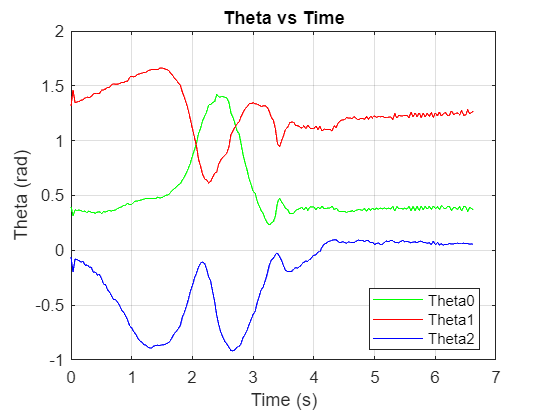

% Plot theta vs time
plot(tspan,theta0,'g')
hold on
plot(tspan,theta1,'r')
plot(tspan,theta2,'b')
hold off
title("Theta vs Time")
xlabel("Time (s)")
ylabel("Theta (rad)")
legend("Theta0","Theta1","Theta2","Location","best")
grid on

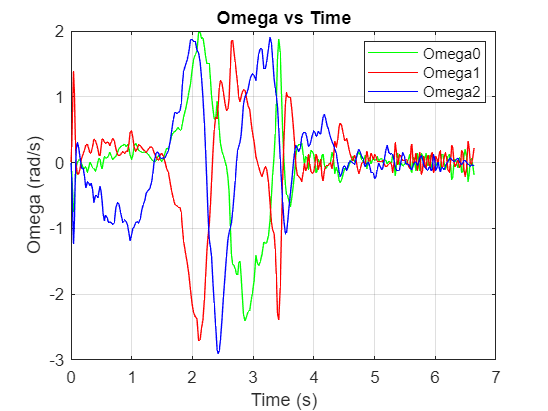


% Plot omega vs time
plot(out.tout,out.omega0(:),'g')
hold on
plot(out.tout,out.omega1(:),'r')
plot(out.tout,out.omega2(:),'b')
hold off
title("Omega vs Time")
xlabel("Time (s)")
ylabel("Omega (rad/s)")
legend("Omega0","Omega1","Omega2","Location","best")
grid on

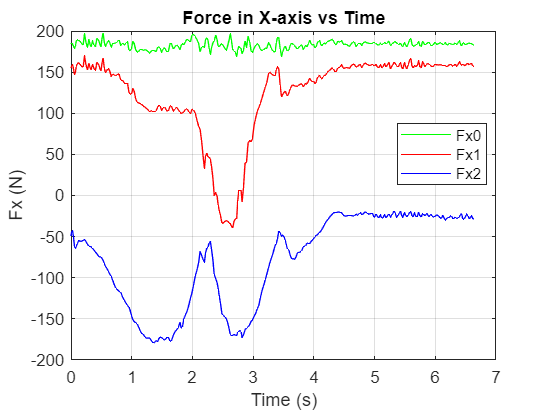


% Plot Force in X-axis
plot(out.tout,out.J0force(1,:)','g')
hold on
plot(out.tout,out.J1force(1,:)','r')
plot(out.tout,out.J2force(1,:)','b')
hold off
title("Force in X-axis vs Time")
xlabel("Time (s)")
ylabel("Fx (N)")
legend("Fx0","Fx1","Fx2","Location","best")
grid on

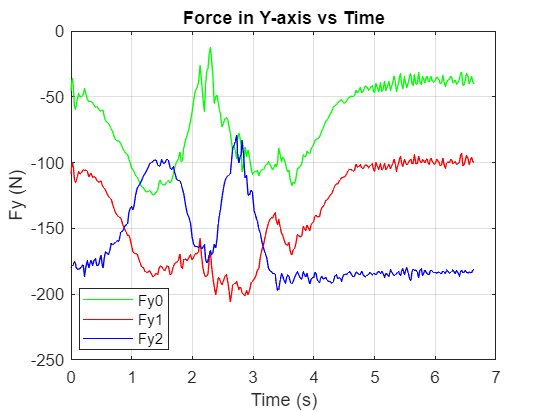


% Plot Force in Y-axis
plot(out.tout,out.J0force(2,:)','g')
hold on
plot(out.tout,out.J1force(2,:)','r')
plot(out.tout,out.J2force(2,:)','b')
hold off
title("Force in Y-axis vs Time")
xlabel("Time (s)")
ylabel("Fy (N)")
legend("Fy0","Fy1","Fy2","Location","best")
grid on

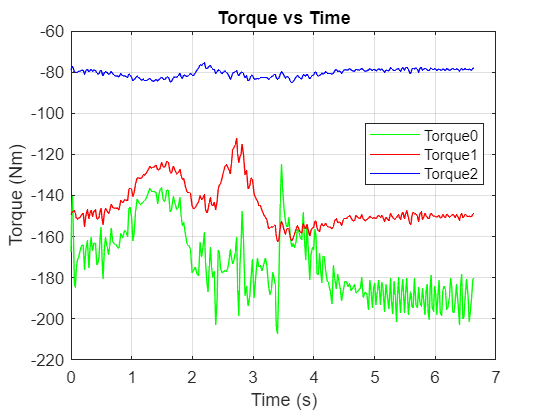


% Plot Torque
plot(out.tout,out.J0torque(3,:)','g')
hold on
plot(out.tout,out.J1torque(3,:)','r')
plot(out.tout,out.J2torque(3,:)','b')
hold off
title("Torque vs Time")
xlabel("Time (s)")
ylabel("Torque (Nm)")
legend("Torque0","Torque1","Torque2","Location","best")
grid on

% Energy estimate
energy = params.mb*params.g*(y0ref(end) - y0ref(1))

energy = 164.0868


% Energy integration
Fx0 = -interp1(out.tout,out.J0force(1,:)',tspan);
Fx1 = -interp1(out.tout,out.J1force(1,:)',tspan);
Fx2 = -interp1(out.tout,out.J2force(1,:)',tspan);
Fy0 = -interp1(out.tout,out.J0force(2,:)',tspan);
Fy1 = -interp1(out.tout,out.J1force(2,:)',tspan);
Fy2 = -interp1(out.tout,out.J2force(2,:)',tspan);
T0 = interp1(out.tout,out.J0torque(3,:)',tspan);
T1 = interp1(out.tout,out.J1torque(3,:)',tspan);
T2 = interp1(out.tout,out.J2torque(3,:)',tspan);

% % plot function Fx
% plot(x0ref,Fx0,'g')
% hold on
% plot(x1ref,Fx1,'r')
% plot(x2ref,Fx2,'b')
% hold off
% title("Fx(N) vs X(m)")
% xlabel("X(m)")
% ylabel("Fx(N)")
% legend("Fx0","Fx1","Fx2","Location","best")
% grid on
% 
% % plot function Fy
% plot(y0ref,Fy0,'g')
% hold on
% plot(y1ref,Fy1,'r')
% plot(y2ref,Fy2,'b')
% hold off
% title("Fy(N) vs Y(m)")
% xlabel("Y(m)")
% ylabel("Fy(N)")
% legend("Fy0","Fy1","Fy2","Location","best")
% grid on

% % plot function T
% plot(theta0,T0,'g')
% hold on
% plot(theta1,T1,'r')
% plot(theta2,T2,'b')
% hold off
% title("T(Nm) vs Theta(rad)")
% xlabel("Theta(rad)")
% ylabel("T(Nm)")
% legend("T0","T1","T2","Location","best")
% grid on

Etranx0 = sum((Fx0(2:end) + Fx0(1:end-1))/2 .* (x0ref(2:end) - x0ref(1:end-1)))

Etranx0 = 94.3996

Etranx1 = sum((Fx1(2:end) + Fx1(1:end-1))/2 .* (x1ref(2:end) - x1ref(1:end-1)))

Etranx1 = 33.9775

Etranx2 = sum((Fx2(2:end) + Fx2(1:end-1))/2 .* (x2ref(2:end) - x2ref(1:end-1)))

Etranx2 = -47.5076

Etrany0 = sum((Fy0(2:end) + Fy0(1:end-1))/2 .* (y0ref(2:end) - y0ref(1:end-1)))

Etrany0 = 10.7444

Etrany1 = sum((Fy1(2:end) + Fy1(1:end-1))/2 .* (y1ref(2:end) - y1ref(1:end-1)))

Etrany1 = 44.9935

Etrany2 = sum((Fy2(2:end) + Fy2(1:end-1))/2 .* (y2ref(2:end) - y2ref(1:end-1)))

Etrany2 = 31.3332

Erotate0 = sum((T0(2:end) + T0(1:end-1))/2 .* (theta0(2:end) - theta0(1:end-1)))

Erotate0 = -0.3691

Erotate1 = sum((T1(2:end) + T1(1:end-1))/2 .* (theta1(2:end) - theta1(1:end-1)))

Erotate1 = 12.2809

Erotate2 = sum((T2(2:end) + T2(1:end-1))/2 .* (theta2(2:end) - theta2(1:end-1)))

Erotate2 = -12.8920


Etotal = Etranx0 + Etranx1 + Etranx2 + Etrany0 + Etrany1 + Etrany2 + Erotate0 + Erotate1 + Erotate2

Etotal = 166.9605